# FILE PER IL CALCOLO DEL PUNTEGGIO DEL CONTROLLORE PROGETTATO

clear all
close all
clc

addpath("controllori")
addpath("file_mat_init")
addpath("modelli")

load file_mat_init\ctrl1.mat
load file_mat_init\ctrl2.mat

nome_gruppo = "Gruppo G";

system=ElasticRoboticSystem();
st=system.getSamplingPeriod;

cs=ControlledSystemScara(system,nome_gruppo);



max_acc=6;
rest_time=0.1;
ctrl = CascadeController(st,@idynRigid,...
                Kp1_pos,Kp1_vel,Ki1_vel,Kaw1,...
                Kp2_pos,Kp2_vel,Ki2_vel,Kaw2,...
                Wn_notch1,xci_z1,xci_p1,...
                Wn_notch2,xci_z2,xci_p2,...
                Tf1_pos,Tf1_vel,...
                Tf2_pos,Tf2_vel);

cs.setController(ctrl);

ans =   CascadeController with properties:

    PI1vel_Fn_Fpb: [1×1 PI_FN_FBP]
        P1pos_Fpb: [1×1 P_FPB]
    PI2vel_Fn_Fpb: [1×1 PI_FN_FBP]
        P2pos_Fpb: [1×1 P_FPB]
            model: @idynRigid

cs.setMaxAcceleration(max_acc);
cs.setRestTime(rest_time);
cs.moveTo([0 0]); % cambia punto di lavoro

% simulo il sistema per la valutazione
% "fast" fa 5 esecuzioni
% "complete" fa 5 x 5 esecuzioni (modalità esame)
tic
[score,results]=cs.evalution("complete");

iteration 1, score = 29.848825
iteration 2, score = 29.832871
iteration 3, score = 29.864160
iteration 4, score = 29.874378
iteration 5, score = 29.874384
iteration 6, score = 29.872843
iteration 7, score = 29.853081
iteration 8, score = 29.870505
iteration 9, score = 29.883559
iteration 10, score = 29.864414
iteration 11, score = 29.841524
iteration 12, score = 29.835567
iteration 13, score = 29.860457
iteration 14, score = 29.887355
iteration 15, score = 29.901125
iteration 16, score = 29.881493
iteration 17, score = 29.917465
iteration 18, score = 29.859331
iteration 19, score = 29.863571
iteration 20, score = 29.917920
iteration 21, score = 29.876491
iteration 22, score = 29.843399
iteration 23, score = 29.920719
iteration 24, score = 29.902483
iteration 25, score = 29.880417


computation_time=toc;
simulated_time=sum([results.Ttot]);
fprintf('Real-time factor = %f\n',simulated_time/computation_time)

Real-time factor = 0.986723


% grafico i risultati
fprintf('lo score è %f\n',score);

lo score è 29.873133


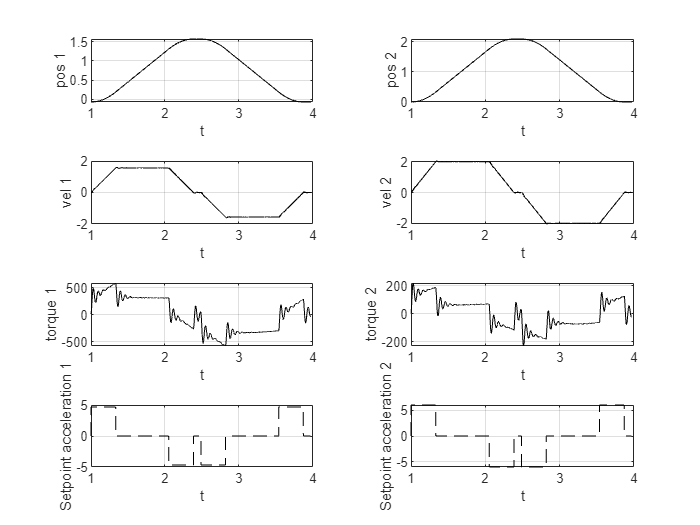

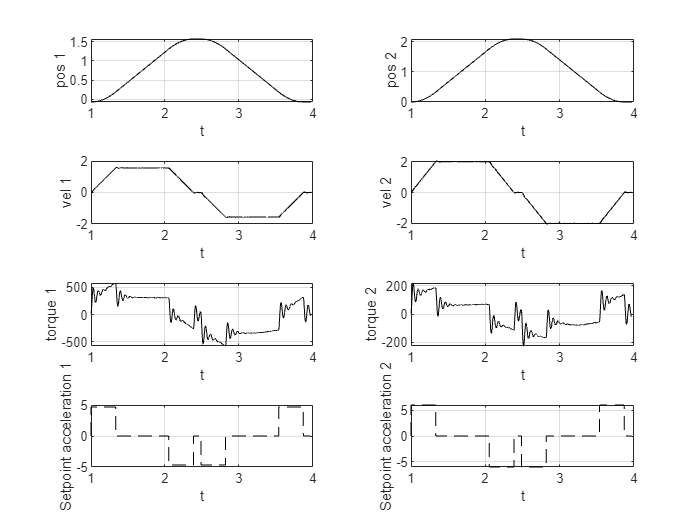

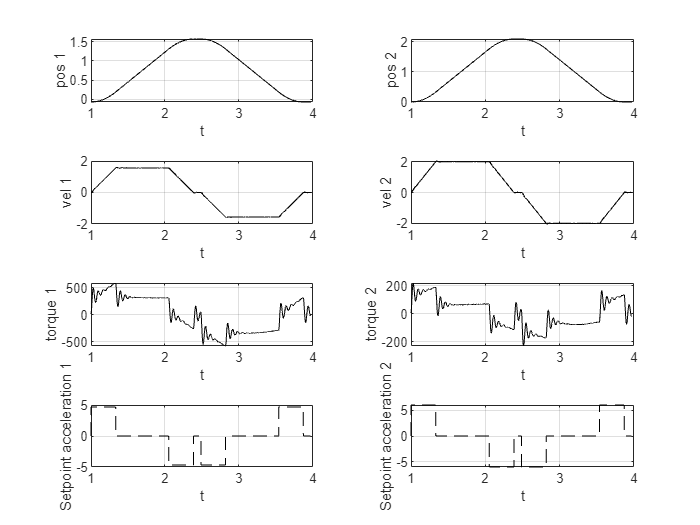

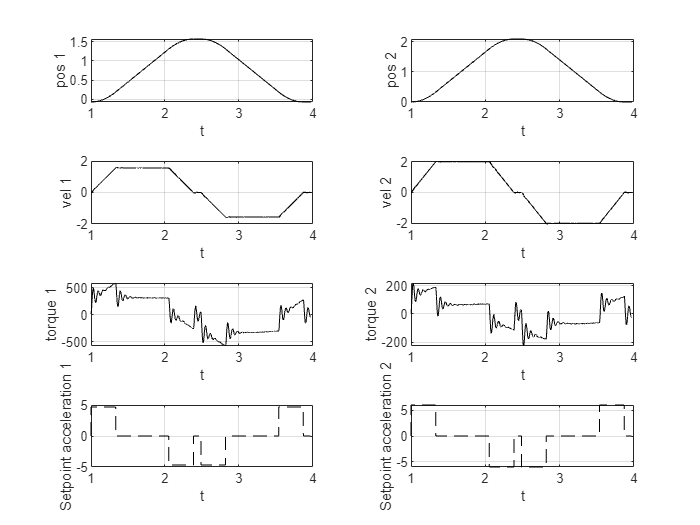

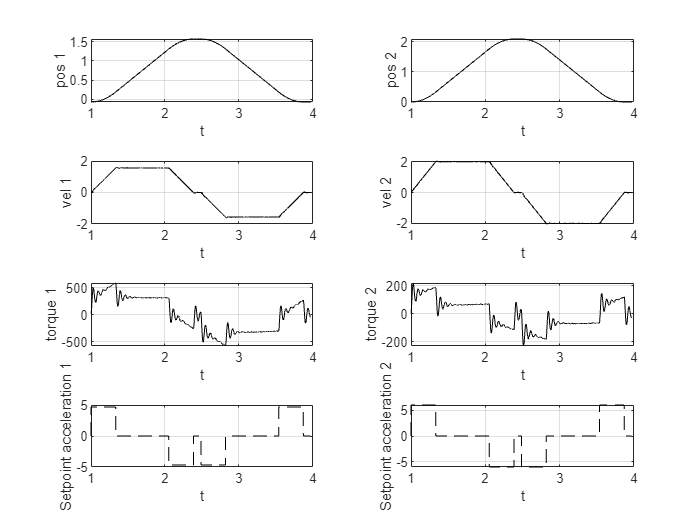

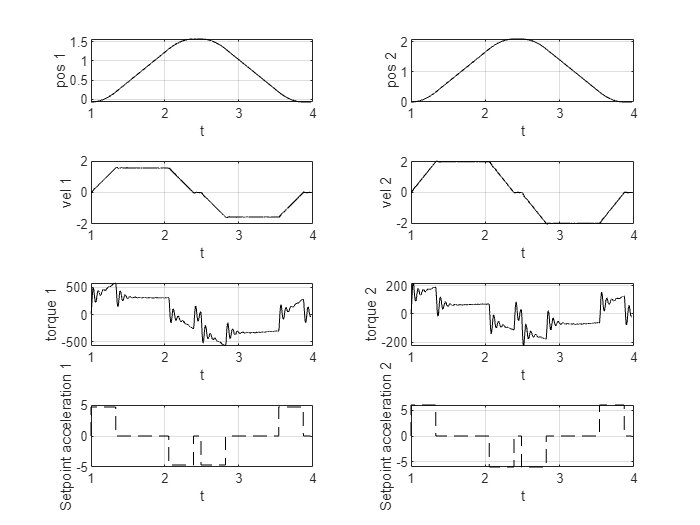

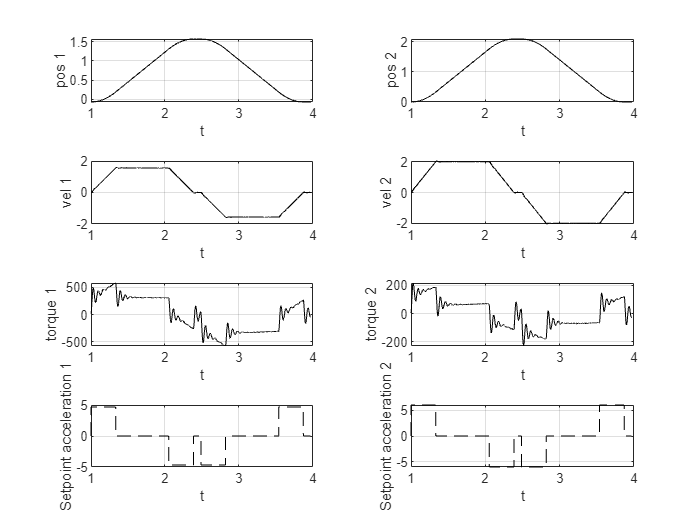

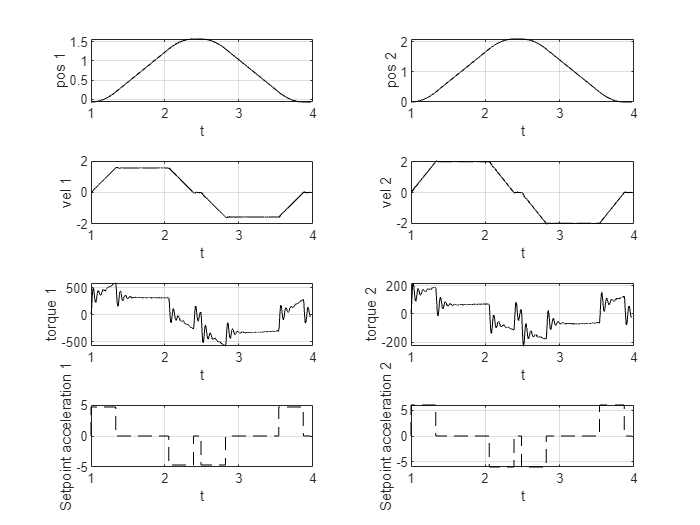

warning off
cs.showResults(results)